% [A0,m0] = imread("butterfly_3x_CONV1_flp.bin", 'bin');
% [A1,m1] = imread("butterfly_3x_GR_flp.bin", 'bin');
% [A2,m2] = imread("butterfly_3x_GT_u8.bin", 'bin');
% [A3,m3] = imread("butterfly_3x_LR_u8.bin", 'bin');

% imwrite(A0,m0,"butterfly_3x_CONV1_flp.png")
% imwrite(A1,m1,"butterfly_3x_GR_flp.png")
% imwrite(A2,m2,"butterfly_3x_GT_u8.png")
% imwrite(A3,m3,"butterfly_3x_LR_u8.png")

% Golden Reference for conv1
fid = fopen('butterfly_3x_CONV1_flp.bin','r')

fid = 3

img = fread(fid, [255, 255], 'float32', 0, 'l'); % 'l' little-endian
fclose(fid);
img = img'                 % transpose (MATLAB reads column-major)

img =          0         0         0    0.0071    0.0030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0000    0.0126    0.0188    0.0136         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

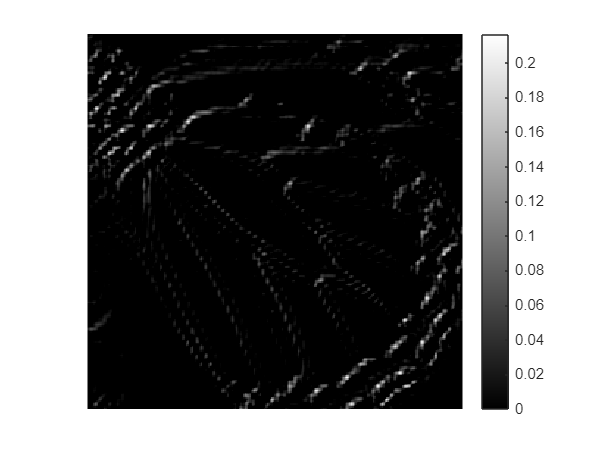

imagesc(img)                % imagesc() automatically rescales Y values
colormap gray; axis image off; colorbar


% img = img .* 255

% I think this is the Super Resolution Golden Reference? idk
% Or maybe it's the bicubic baseline?
fid = fopen('butterfly_3x_GT_u8.bin','r');
img = fread(fid, [255, 255], 'uint8', 0, 'l'); % 'l' little-endian
fclose(fid);
img = img'                  % transpose (MATLAB reads column-major)

img =     44    55    75    84    96    98   102   102   103   106   108   107   111   113   110   110   110   108   106   104   104   103    99    98   100   100    98    98    92    92    90    88    86    84    83    82    83    79    77    76    76    75    74    70    69    69    70    69    67    70
    39    44    51    66    84    90    93   101   108   110   108   111   113   109   109   110   110   111   109   107   106   104   103   101    97    98   100    96    91    94    90    86    82    85    84    82    82    79    77    77    77    75    73    73    68    67    68    69    70    70
    72    47    41    47    56    63    82    95   103   112   111   112   113   109   109   112   111   111   108   107   104   103   102   103    98    98   100    93    94    90    89    89    85    84    83    82    80    79    77    74    76    75    72    70    69    71    69    69    70    71
   198   120    39    41    40    59    78    81    99   112   114   111   111   113   113 

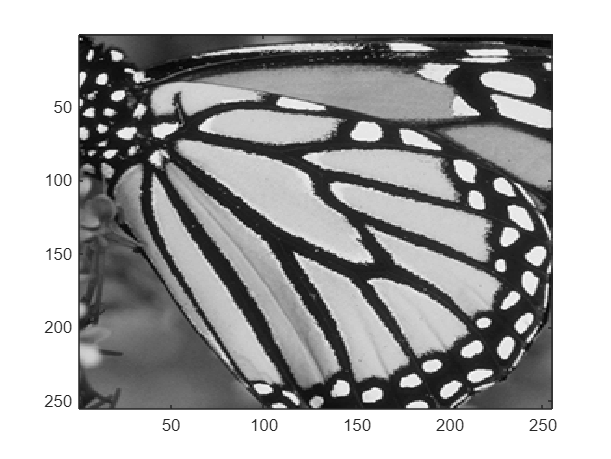

imagesc(img)                % imagesc() automatically rescales Y values


% img = img .* 255

% I think this is the Super Resolution Golden Reference? idk
% Or maybe it's the bicubic baseline?
fid = fopen('butterfly_3x_GR_flp.bin','r');
GRimg = fread(fid, [255, 255], 'float32', 0, 'l'); % 'l' little-endian
fclose(fid);
GRimg = GRimg';                  % transpose (MATLAB reads column-major)
GRimg = GRimg .* 255

GRimg =    54.5508   51.8413   61.4016   76.1653   89.9029   92.8797   96.6948   95.9731  100.3883  102.7774  105.2358  106.8685  109.9183  110.1751  110.2648  109.2408  109.2383  107.1099  105.8036  105.1327  102.5132  101.3846  101.8948  100.6281  100.7293   98.8981   98.6257   98.0212   93.6105   91.8109   90.6634   86.4500   86.1055   84.2571   83.4573   81.7250   79.8466   79.0684   78.3850   77.0629   76.3021   74.3575   72.4730   71.8367   69.6583   69.4078   68.0130   68.1152   69.9181   69.6408
   54.1071   54.0665   61.8834   71.6582   86.2512   93.9260   98.3028   97.4951  100.6425  103.8812  107.1592  107.7513  109.5667  109.7506  109.3855  109.0616  109.3571  107.8201  106.1027  105.0597  103.5117  102.8772  102.5231  100.9802  100.8317   99.5207   98.6104   97.6078   94.3673   91.8571   89.7663   86.1683   86.2833   84.0850   83.1930   81.7335   80.3330   78.7062   78.4760   77.1819   76.6351   74.6469   72.7326   71.8292   70.2214   69.8760   68.5164   68.4324   69.3355 

GRimg = floor(GRimg)

GRimg =     54    51    61    76    89    92    96    95   100   102   105   106   109   110   110   109   109   107   105   105   102   101   101   100   100    98    98    98    93    91    90    86    86    84    83    81    79    79    78    77    76    74    72    71    69    69    68    68    69    69
    54    54    61    71    86    93    98    97   100   103   107   107   109   109   109   109   109   107   106   105   103   102   102   100   100    99    98    97    94    91    89    86    86    84    83    81    80    78    78    77    76    74    72    71    70    69    68    68    69    69
    65    63    62    58    64    75    92   101   105   108   110   110   111   111   111   109   110   110   110   108   105   103   101    99   100    98    96    94    93    90    89    86    86    84    83    81    80    78    78    76    76    74    72    71    69    69    68    68    68    69
    90    84    66    47    43    50    75   100   111   112   111   111   113   111   11

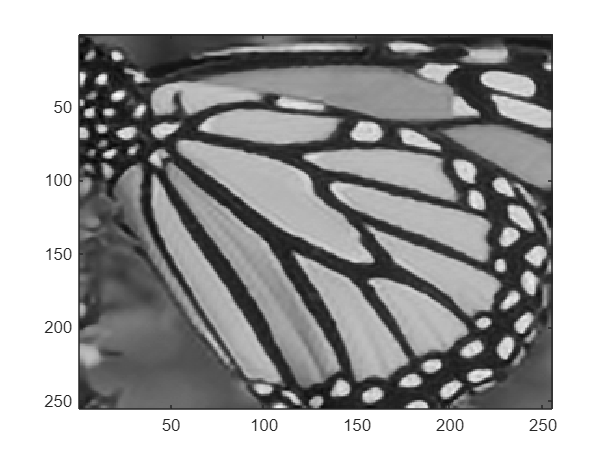

imagesc(GRimg)                % imagesc() automatically rescales Y values

% Input LR image for SRCNN
fid = fopen('butterfly_3x_LR_u8.bin','r');
LRimg = fread(fid, [255, 255], 'uint8', 0, 'l'); % 'l' little-endian
fclose(fid);
LRimg = LRimg'                 % transpose (MATLAB reads column-major)

LRimg =     55    58    63    72    80    88    95   101   105   108   110   111   112   112   111   111   110   109   107   106   104   103   101   100   100    99    97    96    94    92    89    87    86    84    83    82    80    79    78    77    76    74    73    71    70    69    69    69    69    70
    57    59    63    69    76    84    92   100   104   108   110   111   111   111   111   111   110   109   108   106   105   103   102   101   100    99    97    96    94    92    89    87    86    84    83    82    80    79    78    77    76    74    73    71    70    69    69    69    69    70
    65    65    64    63    66    74    85    96   103   109   112   113   112   111   111   111   111   110   109   108   106   104   102   101   100    98    97    95    93    91    89    87    86    85    83    82    80    79    78    77    75    74    72    71    70    69    68    68    69    70
    75    72    65    55    51    60    76    90   100   110   115   116   113   111   11

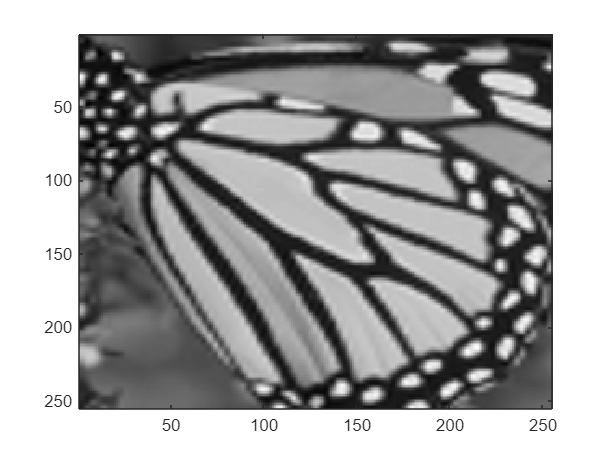

imagesc(LRimg)                % imagesc() automatically rescales Y values

% SRCNN Output
fid = fopen('SRCNN_output.bin','r');
SRCNN_Out_img = fread(fid, [255, 255], 'uint8', 0, 'l'); % 'l' little-endian
fclose(fid);
SRCNN_Out_img = SRCNN_Out_img'                 % transpose (MATLAB reads column-major)

SRCNN_Out_img =     54    51    61    76    89    92    96    95   100   102   105   106   109   110   110   109   109   107   105   105   102   101   101   100   100    98    98    98    93    91    90    86    86    84    83    81    79    79    78    77    76    74    72    71    69    69    68    68    69    69
    54    54    61    71    86    93    98    97   100   103   107   107   109   109   109   109   109   107   106   105   103   102   102   100   100    99    98    97    94    91    89    86    86    84    83    81    80    78    78    77    76    74    72    71    70    69    68    68    69    69
    65    63    62    58    64    75    92   101   105   108   110   110   111   111   111   109   110   110   110   108   105   103   101    99   100    98    96    94    93    90    89    86    86    84    83    81    80    78    78    76    76    74    72    71    69    69    68    68    68    69
    90    84    66    47    43    50    75   100   111   112   111   111   113   

imagesc(SRCNN_Out_img)                % imagesc() automatically rescales Y values

% % Ground Reference for the SRCNN
% fid = fopen('SRCNN_GR.bin','r');
% GRimg = fread(fid, [255, 255], 'uint8', 0, 'l'); % 'l' little-endian
% fclose(fid);
% GRimg = GRimg'                  % transpose (MATLAB reads column-major)
% imagesc(GRimg)                % imagesc() automatically rescales Y values

% Check equality of matrices
isequal(SRCNN_Out_img, GRimg)

ans = logical
   1
